# Preliminary Investigation of Data

File used to understand trends of data and brainstorm algorithm to classify exercise as correct or incorrect

Exercise: Paloff Press. Sampling frequency is 100Hz. 

addpath('Data\')
clc, clear

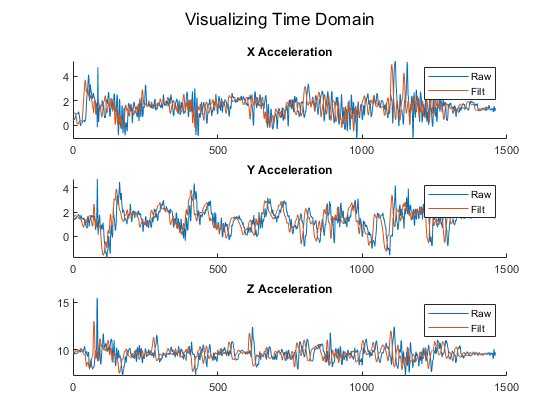

%5 point moving average filter
g1_time = ParseMatlabAppFinal('G1');
g1_filt = move_avg_filt(g1_time, 5);
b1_time = ParseMatlabAppFinal('B1');
b1_filt = move_avg_filt(b1_time, 5);

%visualize time domain for filtered vs unfiltered
clf
figure()
sgtitle('Visualizing Time Domain')
subplot(3,1,1)
hold on
plot(g1_time.Accel(:,1))
plot(g1_filt(:,1))
title('X Acceleration')
hold off
legend('Raw', 'Filt')
subplot(3,1,2)
hold on
plot(g1_time.Accel(:,2))
plot(g1_filt(:,2))
title('Y Acceleration')
hold off
legend('Raw', 'Filt')
subplot(3,1,3)
hold on
plot(g1_time.Accel(:,3))
plot(g1_filt(:,3))
title('Z Acceleration')
hold off
legend('Raw', 'Filt')

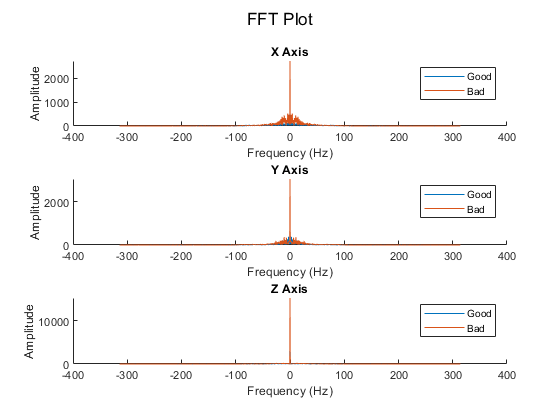

% Visualize Frequency Domain for 1 example of good vs. bad (filtered)
g1 = fft_from_time(g1_filt, 100);
b1 = fft_from_time(b1_filt, 100);
figure()
clf
subplot(3,1,1)
sgtitle('FFT Plot')
hold on
plot(g1(:,1), abs(g1(:,2)))
plot(b1(:,1), abs(b1(:,2)))
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
legend('Good', 'Bad')
hold off
subplot(3,1,2)
hold on
plot(g1(:,1), abs(g1(:,3)))
plot(b1(:,1), abs(b1(:,3)))
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
legend('Good', 'Bad')
hold off
subplot(3,1,3)
hold on
plot(g1(:,1), abs(g1(:,4)))
plot(b1(:,1), abs(b1(:,4)))
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
legend('Good', 'Bad')
hold off

%Get filtered data for good trials
g1_time = ParseMatlabAppFinal('G1');
g1_filt = move_avg_filt(g1_time, 5);
g2_time = ParseMatlabAppFinal('G2');
g2_filt = move_avg_filt(g2_time, 5);
g3_time = ParseMatlabAppFinal('G3');
g3_filt = move_avg_filt(g3_time, 5);
g4_time = ParseMatlabAppFinal('G4');
g4_filt = move_avg_filt(g4_time, 5);

%take fft and remove the 0 frequency
g1 = remove_0(fft_from_time(g1_filt, 100));
g2 = remove_0(fft_from_time(g2_filt, 100));
g3 = remove_0(fft_from_time(g3_filt, 100));
g4 = remove_0(fft_from_time(g4_filt, 100));

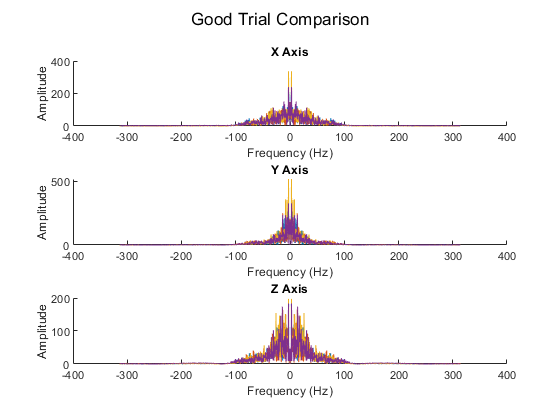

clf
figure();
sgtitle('Good Trial Comparison')
subplot(3,1,1)
hold on
plot(g1(:,1), abs(g1(:,2)))
plot(g2(:,1), abs(g2(:,2)))
plot(g3(:,1), abs(g3(:,2)))
plot(g4(:,1), abs(g4(:,2)))
hold off
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
subplot(3,1,2)
hold on
plot(g1(:,1), abs(g1(:,3)))
plot(g2(:,1), abs(g2(:,3)))
plot(g3(:,1), abs(g3(:,3)))
plot(g4(:,1), abs(g4(:,3)))
hold off
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
subplot(3,1,3)
hold on
plot(g1(:,1), abs(g1(:,4)))
plot(g2(:,1), abs(g2(:,4)))
plot(g3(:,1), abs(g3(:,4)))
plot(g4(:,1), abs(g4(:,4)))
hold off
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

%Get filtered data for bad trials
b1_time = ParseMatlabAppFinal('B1');
b1_filt = move_avg_filt(b1_time, 5);
b2_time = ParseMatlabAppFinal('B2');
b2_filt = move_avg_filt(b2_time, 5);
b3_time = ParseMatlabAppFinal('B3');
b3_filt = move_avg_filt(b3_time, 5);
b4_time = ParseMatlabAppFinal('B4');
b4_filt = move_avg_filt(b4_time, 5);

%take fft and remove 0 frequency
b1 = remove_0(fft_from_time(b1_filt, 100));
b2 = remove_0(fft_from_time(b2_filt, 100));
b3 = remove_0(fft_from_time(b3_filt, 100));
b4 = remove_0(fft_from_time(b4_filt, 100));

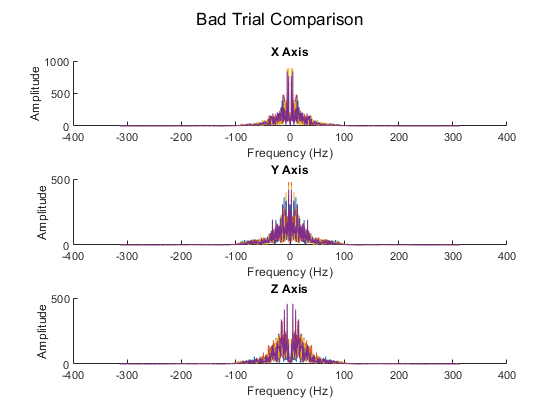

clf
figure();
sgtitle('Bad Trial Comparison')
subplot(3,1,1)
hold on
plot(b1(:,1), abs(b1(:,2)))
plot(b2(:,1), abs(b2(:,2)))
plot(b3(:,1), abs(b3(:,2)))
plot(b4(:,1), abs(b4(:,2)))
hold off
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
subplot(3,1,2)
hold on
plot(b1(:,1), abs(b1(:,3)))
plot(b2(:,1), abs(b2(:,3)))
plot(b3(:,1), abs(b3(:,3)))
plot(b4(:,1), abs(b4(:,3)))
hold off
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
subplot(3,1,3)
hold on
plot(b1(:,1), abs(b1(:,4)))
plot(b2(:,1), abs(b2(:,4)))
plot(b3(:,1), abs(b3(:,4)))
plot(b4(:,1), abs(b4(:,4)))
hold off
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

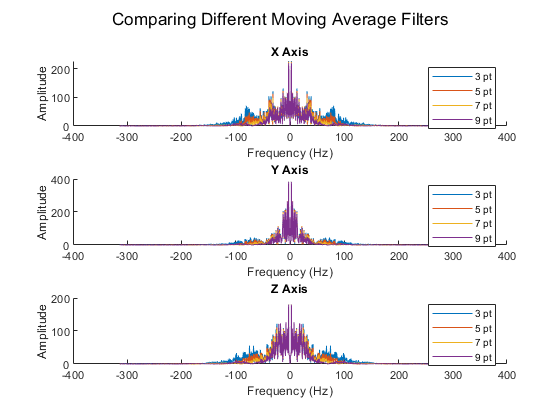

%Comparing different low pass filters (3, 5, 7, 9) pt moving averages
g1_filt3 = move_avg_filt(g1_time, 3);
g1_3 = fft_from_time(g1_filt3, 100);
g1_filt5 = move_avg_filt(g1_time, 5);
g1_5 = fft_from_time(g1_filt5, 100);
g1_filt7 = move_avg_filt(g1_time, 7);
g1_7 = fft_from_time(g1_filt7, 100);
g1_filt9 = move_avg_filt(g1_time, 9);
g1_9 = fft_from_time(g1_filt9, 100);

%remove 0 frequency
g1_3 = remove_0(g1_3);
g1_5 = remove_0(g1_5);
g1_7 = remove_0(g1_7);
g1_9 = remove_0(g1_9);

clf
figure();
sgtitle('Comparing Different Moving Average Filters')
subplot(3,1,1)
hold on
plot(g1_3(:,1), abs(g1_3(:,2)))
plot(g1_5(:,1), abs(g1_5(:,2)))
plot(g1_7(:,1), abs(g1_7(:,2)))
plot(g1_9(:,1), abs(g1_9(:,2)))
hold off
legend('3 pt', '5 pt', '7 pt', '9 pt')
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
subplot(3,1,2)
hold on
plot(g1_3(:,1), abs(g1_3(:,3)))
plot(g1_5(:,1), abs(g1_5(:,3)))
plot(g1_7(:,1), abs(g1_7(:,3)))
plot(g1_9(:,1), abs(g1_9(:,3)))
hold off
legend('3 pt', '5 pt', '7 pt', '9 pt')
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

subplot(3,1,3)
hold on
plot(g1_3(:,1), abs(g1_3(:,4)))
plot(g1_5(:,1), abs(g1_5(:,4)))
plot(g1_7(:,1), abs(g1_7(:,4)))
plot(g1_9(:,1), abs(g1_9(:,4)))
hold off
legend('3 pt', '5 pt', '7 pt', '9 pt')
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')

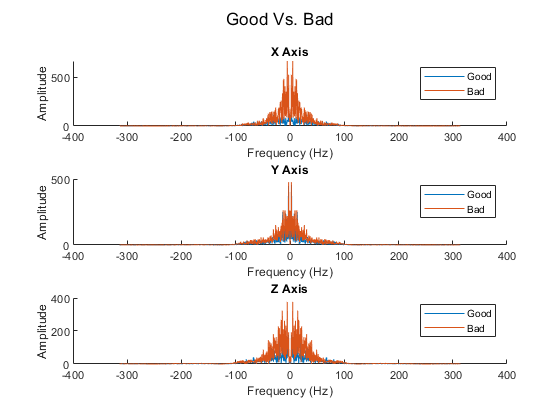

%Compare Good vs Bad for 5 point moving average filter
%Removed 0 frequency to make differences easier to see
g2_filt5 = move_avg_filt(g2_time, 5);
g2_5 = fft_from_time(g2_filt5, 100);
g2_5 = remove_0(g2_5);
b2_filt5 = move_avg_filt(b2_time, 5);
b2_5 = fft_from_time(b2_filt5, 100);
b2_5 = remove_0(b2_5);

clf
figure()
sgtitle('Good Vs. Bad')
subplot(3,1,1)
hold on
plot(g2_5(:,1), abs(g2_5(:,2)))
plot(b2_5(:,1), abs(b2_5(:,2)))
legend('Good', 'Bad')
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

subplot(3,1,2)
hold on
plot(g2_5(:,1), abs(g2_5(:,3)))
plot(b2_5(:,1), abs(b2_5(:,3)))
legend('Good', 'Bad')
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

subplot(3,1,3)
hold on
plot(g2_5(:,1), abs(g2_5(:,4)))
plot(b2_5(:,1), abs(b2_5(:,4)))
legend('Good', 'Bad')
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

### Possible Algorithm Idea (ended up failing)

Calculate number of peaks within a threshold of the highest (excluding 0 Hz) for good and bad. From looking at the graphs (and performing the exercise), it seems like when you do the exercise wrong, there will be more peaks. Additionally, there will be peaks with a higher amplitude at higher frequencies (but this basic idea doesn't take that into account). As the output shows, this ended up not showing a trend.

good1_peak = do_everything_calc_peaks('G1', 5, 100, 2, .25)

good1_peak = 30

good2_peak = do_everything_calc_peaks('G2', 5, 100, 2, .25)

good2_peak = 39

good3_peak = do_everything_calc_peaks('G3', 5, 100, 2, .25)

good3_peak = 13

good4_peak = do_everything_calc_peaks('G4', 5, 100, 2, .25)

good4_peak = 29


bad1_peak = do_everything_calc_peaks('B1', 5, 100, 2, .25)

bad1_peak = 35

bad2_peak = do_everything_calc_peaks('B2', 5, 100, 2, .25)

bad2_peak = 28

bad3_peak = do_everything_calc_peaks('B3', 5, 100, 2, .25)

bad3_peak = 13

bad4_peak = do_everything_calc_peaks('B4', 5, 100, 2, .25)

bad4_peak = 13

good1_comp = do_everything('G1', 5, 100);
good2_comp = do_everything('G2', 5, 100);
good3_comp = do_everything('G3', 5, 100);
good4_comp = do_everything('G4', 5, 100);

bad1_comp = do_everything('B1', 5, 100);
bad2_comp = do_everything('B2', 5, 100);
bad3_comp = do_everything('B3', 5, 100);
bad4_comp = do_everything('B4', 5, 100);

[~, Ig1] = max(good1_comp(:,2))

Ig1 = 713

[~, Ib1] = max(bad1_comp(:,2))

Ib1 = 820


good1_comp(Ig1)

ans = -2.6235

bad1_comp(Ib1)

ans = 4.2743

function num_peaks = calc_peaks(freq_data, dim, prop)
    %calculates the number of peaks within a threshold from fft data
    %freq_data: fft data
    %dim: dimension to calculate peaks for (x, y, or z axis)
    %prop: proportion to calculate threshold off of
    %note: assumes the mag of 0 freq has been set to 0
    
    max_mag = max(abs(freq_data(:, dim)));
    cut_off = max_mag * prop;
    data = abs(freq_data(:, dim));
    peaks = data(data > cut_off);
    num_peaks = length(peaks) / 2; %only care about positive
    
    for i=1:num_peaks %from dad dance, bit confused, could be better
        if abs(peaks(i) - peaks(i+1)) <4
            num_peaks = num_peaks - 1;
        end
    end
end

function freq_data = remove_0(freq_data)
    %removes the 0 frequency from data (sets amplitude to 0)
    %freq_data: fft data
    for i=2:4
        [~, Index] = max(freq_data(:,i));
        freq_data(Index, i) = 0;
    end
end

function num_peaks = do_everything_calc_peaks(file_name, low_pass_num, Fs, dim, prop)
    time_data = ParseMatlabAppFinal(file_name);
    filt_data = move_avg_filt(time_data, low_pass_num);
    fft_data = fft_from_time(filt_data, Fs);
    fft_data = remove_0(fft_data);
    
    num_peaks = calc_peaks(fft_data, dim, prop);
end

function data = do_everything(file_name, low_pass_num, Fs)
    % get data from the file to filtered and 0 freq removed
    % file_name: name of data file
    % low_pass_num: number of points to use for moving average filter
    % Fs: sampling rate
    time_data = ParseMatlabAppFinal(file_name);
    filt_data = move_avg_filt(time_data, low_pass_num);
    fft_data = fft_from_time(filt_data, Fs);
    data = remove_0(fft_data);
end